## Step 1: Load and prepare data. 

The data must be normalized for use in a CNN prediction model.

%addpath(genpath('MATLAB-Drive'))
try
    gd = gpuDevice;
    exEn = 'gpu';
catch ME
    warning("GPU not found!");
    exEn = 'cpu';
end
load dataset_CuttingTools.mat

% normalize the regression outputs
ytrain_min = min(dataTrain.ylabel(:));
ytrain_max = max(dataTrain.ylabel(:));
ytrain = normalize(dataTrain.ylabel(:),'range',[0,1]);

yval_min = min(dataValidation.ylabel(:));
yval_max = max(dataValidation.ylabel(:));
yval = dataValidation.ylabel(:);

xtrain_norm = zeros(size(predictorsTrain.Var1));
xtest_norm = zeros(size(predictorsTest.Var1));
xval_norm = zeros(size(predictorsValidation.Var1));

% normalize each predictor between 0 and 1
for i = 1:width(predictorsTrain.Var1)
    xtrain_min(i) = min(table2array(predictorsTrain.Var1(:,i)));
    xtrain_max(i) = max(table2array(predictorsTrain.Var1(:,i)));
    xtrain_norm(:,i) = normalize(table2array(predictorsTrain.Var1(:,i),'range',[0,1]));
    
    xtest_min(i) = min(table2array(predictorsTest.Var1(:,i)));
    xtest_max(i) = max(table2array(predictorsTest.Var1(:,i)));
    xtest_norm(:,i) = normalize(table2array(predictorsTest.Var1(:,i),'range',[0,1]));
    
    xval_min(i) = min(table2array(predictorsValidation.Var1(:,i)));
    xval_max(i) = max(table2array(predictorsValidation.Var1(:,i)));
    xval_norm(:,i) = normalize(table2array(predictorsValidation.Var1(:,i),'range',[0,1]));
end


% 70-30 split
imdsTrain = dataTrain(1:196,:);
imdsValidation = vertcat(dataTrain(197:end,:),dataValidation(:,:));

figure(1); 
subplot(1,3,1)
imshow(imread(dataTrain.filename(1)));
title('sample training data image');
subplot(1,3,2)
imshow(imread(dataTest.filename(1)));
title('sample testing data image');
subplot(1,3,3)
imshow(imread(dataValidation.filename(1)));
title('sample Validation data image');

% binary classification task
sourceTask = "binary"
% sourceTask = "multi"

% Script to create datastore to use for fine-tuning the models
createDatastoreForAllFiles;
% the script produces "source domain" datastores for training and validation
% as well as fine tuning training options (opts_ft)
% the source datastores for training and validation are called
ds_train_src = ds_train;
ds_val_src = ds_val;

classWeights = calculateClassPenalties(ds_train_src.Labels);
classWeights_val = calculateClassPenalties(ds_val_src.Labels);

% compute class penalties from class frequency matrix

% load mean image to use as input to the image input normalization
load ilsvrc_2012_mean.mat;

if strcmp(sourceTask,"binary")
    % create image datastore to use for training the source task
        ds_train_src = imageDatastore(dataTrain.filename,"IncludeSubfolders",true,"LabelSource","foldernames");
        ds_val_src = imageDatastore(dataValidation.filename,"IncludeSubfolders",true,"LabelSource","foldernames");
        
    end

## Step 2: Load and prepare models to use in CNN prediction

models = ["alexnet", "resnet18", "resnet50", "resnet101", "inceptionv3","squeezenet"];

for i = 1:numel(models)
%while i <= numel(models)
%testWeights = 0.001*normalize([1,1,1,5,5,10,10,20],'range',[0,1]);
    % freeze weights of the first layer only by passing
    
    idxFrz = 2;
    [tmpNet, TmpExpNames] = loadPretrainedCNN(models(i),unique(ds_train_src.Labels),"cross",0,idxFrz,[],[], mean_data);
    expNames{i} = TmpExpNames;
    inputSize{i} = tmpNet.Layers(1).InputSize;
    
    [fineTunedNet, valAcc] = finetuneModel(tmpNet,ds_train_src,ds_val_src)
    % remove the commands which replace layer components with MMD loss
    % layer
    fprintf("Fine-tuning validation accuarcy for %s: %2.2f%% \n",expNames{i},100*valAcc);
    % prepare the model for final training
    %regLayer = weightedCompoundLossLayer(2,'regout_NMKMMD_NMSE');
    % replace last 3 network layers (fully connected, softmax and classout)
    % with the regression layers (1 fc layer and its regression output)
    regLayers = [fullyConnectedLayer(1,'Name','fcfinal_end'),...
        regressionLayer('Name','regressionOutput_rmse')];
    lyrsToRemove = {fineTunedNet.Layers(end-2:end).Name};
    % in case model is not a layerGraph, cast it into one
    fineTunedNet = layerGraph(fineTunedNet);
    % remove the layers and replace with regLayers
    fineTunedNet = removeLayers(fineTunedNet,lyrsToRemove);
    sl = fineTunedNet.Layers(end).Name;
    fineTunedNet = addLayers(fineTunedNet,regLayers); 
    learnRate = 50;
    rl = regLayers(1).Name;
    %regLayer = setLearnRateFactor(regLayer(1),learnRate);
    %fprintf('Learn rate factor of %d set for final Regression Layer %s',learnRate,rl)
    %sl = tmpNet.Layers(end-1).Name;
    fineTunedNet = connectLayers(fineTunedNet,sl,rl);
    fprintf('Layer %s not replaced with %s \n', sl, rl);
    %tmpNet(end) = setLearnRateFactor(tmpNet(end),'Weights',50);
    %analyzeNetwork(tmpNet)
    nets{i} = fineTunedNet;
    %ext_feat_src = ex
end
   

pixelRange = [-30 30];
%rotRange = [-15 15];
scaleRange = [0.8 1.2];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange,...
    'RandRotation',pixelRange/2);


## Step 3: Run model training, then predict using the model.

for i = 1:numel(models)
    
    augimdsTrain = augmentedImageDatastore(inputSize{i}(1:2),imdsTrain(:,1:2), ...
        'DataAugmentation',imageAugmenter,'OutputSizeMode','centercrop');
    augimdsValidation = augmentedImageDatastore(inputSize{i}(1:2),imdsValidation(:,1:2));

    options = trainingOptions('adam', ...
        "GradientDecayFactor",0.95,...
        'MiniBatchSize',16, ...
        'MaxEpochs',100, ...
        'LearnRateSchedule','piecewise',...
        'LearnRateDropPeriod',10,...
        'LearnRateDropFactor',0.9,...
        'InitialLearnRate',2e-4, ...
        'L2Regularization',0.002,...
        'Shuffle','never', ...
        'ValidationData',augimdsValidation, ...
        'ValidationFrequency',10, ...
        'ValidationPatience',Inf, ...
        'Verbose',true, ...
        'Plots','training-progress',...
        'ExecutionEnvironment',exEn)
    for j = 1:3
    if exEn == 'gpu'
    reset(gd);
    end
    tic;
    % replace reul_final layer with sigmoid layer(?)
    pretrainedNet = nets{i};
    larray = sigmoidLayer_gpu(1,'sigmoid_final');
    pretrainedNet = replaceLayer(pretrainedNet,'relu_final',larray,'ReconnectBy',"name");
    
    [net, info] = trainNetwork(augimdsTrain,pretrainedNet,options);
    tt = toc;
    % predict outputs directly here
    YPred_j{j} = predict(net,augimdsValidation,'MiniBatchSize',16);
    
    YActual{i} = imdsValidation.ylabel;
        
    % benchmark model predictions
   [mae_val,rmse_val,acc10,acc20,acc30] = benchmarkModelSkill(YPred_j{j},YActual{1})
    % compute j runs of each training loop and store in val_accuracy
    val_accuracy{j} = [acc10,acc20,acc30]
    training_time(j) = tt;
    end
    % model validation accuracy is j-run average of each model
    % model validation 
  YPred{i} = YPred_j{j};
  model_acc = reshape(cell2mat(val_accuracy),[3,j])';
  val_acc_10_avg(i) = mean(model_acc(:,1));
  val_acc_20_avg(i) = mean(model_acc(:,2));  
  val_acc_30_avg(i) = mean(model_acc(:,3));
  trainingTime_avg(i) = mean(training_time(1:j));
    % use the features extracted from final FC layers as inputs to regression
  % model (SVM or similar)
  ypred_re1 = [];
  ypred_re2 = [];
  % Run a script to extract features from resulting model
%   regFlag = "ensemble"
%   fitEnsemblesToExtractedFeatures
%   
%   regFlag = "svm"
%   fitEnsemblesToExtractedFeatures

  %
  % Save all results in model performance struct
  modelPerformance{i} = struct('ModelName',expNames{i}, ...
      'ValidationAccuracy', ...
      [val_acc_10_avg(i),val_acc_20_avg(i),val_acc_30_avg(i)],...
      'TrainingTime',trainingTime_avg(i), ...
      'Predictions',YPred{i},'PredictionsFC',ypred_re1,'PredictionsPool',ypred_re2);
    %% visualize an image feature which strongly activates the trained model's
  % feature extractor layers
  %fc_ds_2 = 'fc_downsampling_2';
  fc_ds_3 = 'fc_downsampling_3';
  filename = expNames{i}+"_results.mat";
  performance = modelPerformance{i};
  save(filename,"performance");
  %I1_fc_downsampled2 = deepDreamImage(net,fc_ds_2,1:410);
    % use the features extracted from final FC layers as inputs to regression
  % model (SVM or similar)
 figs = findall(groot,'Type','Figure');
  % set figures to be all the figures but 1
  figs = figs(2:end);
  close(figs)
  clc;

  % Reset the image and re-compute for newly trained model unless model has
  % no FC downsampling layer
I1 = [];   
try  
%if~strcmp(models(i),"squeezenet")
  I1 = deepDreamImage(net,fc_ds_3,1:128);
%  I2 = deepDreamImage(net,lyrsPool)
%end
catch 
    warning("Layer %s not present in specified model! \n",fc_ds_3)
end
  
  % visualize a selection of the image features 1:72
  if ~strcmp(models(i),"squeezenet") && ~isempty(I1)
  figure(i); clf reset;
  montage(I1(:,:,:,1:128));
  title(sprintf("Visualized features for final feature extraction layer of %s",expNames{i}));
  featureBank_im = expNames{i}+".png"
  saveas(gcf,featureBank_im)
  end
  options
  fprintf("Model name: %s acc_10 = %2.2f % \n ____________________________ \n",expNames{i},100*val_acc_10_avg(i))
end

options =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9500
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 2.0000e-04
     LearnRateScheduleSettings: [1×1 struct]
              L2Regularization: 0.0020
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 100
                 MiniBatchSize: 16
                       Verbose: 1
              VerboseFrequency: 50
                ValidationData: [1×1 augmentedImageDatastore]
           ValidationFrequency: 10
            ValidationPatience: Inf
                       Shuffle: 'never'
                CheckpointPath: ''
          ExecutionEnvironment: 'gpu'
                    WorkerLoad: []
                     OutputFcn: []
                         Plots: 'training-progress'
                SequenceLength: 

Initializing input data normalization.


 %

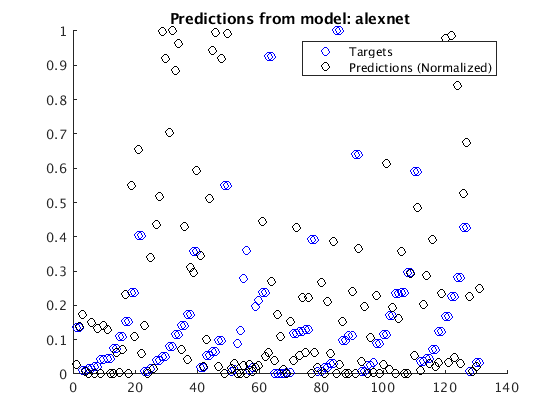

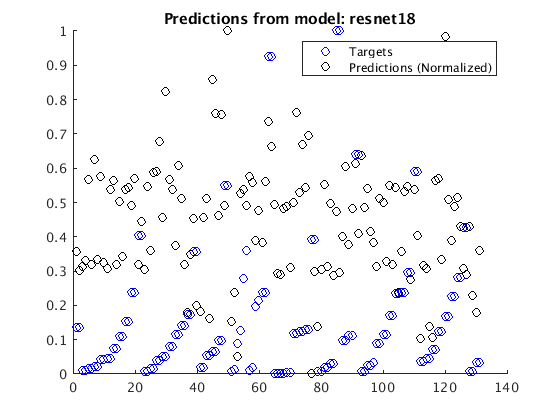

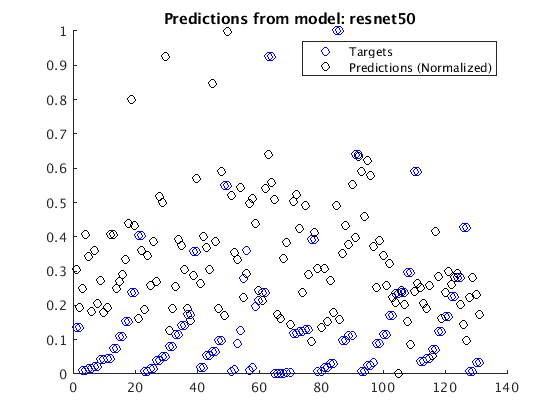

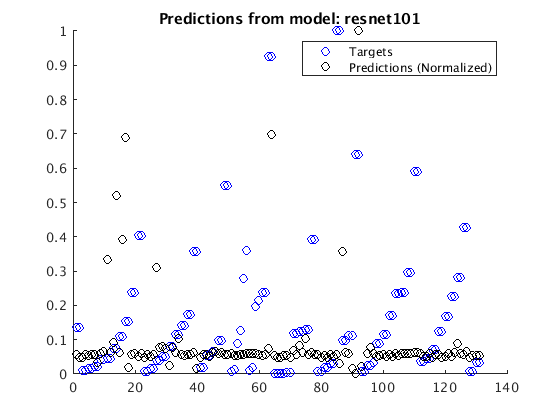

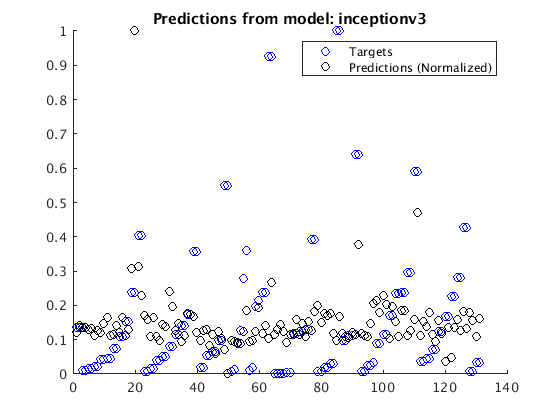

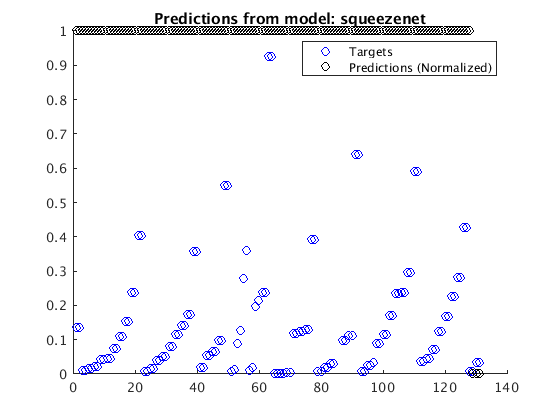

%figure(1); clf reset;

 for i=1:6
    figure(i+1); clf reset;
    predictions(i,:) = modelPerformance{i}.Predictions();
    predictionsNorm(i,:) = normalize(predictions(i,:),'range',[yval_min,yval_max]);
    hold on;
    plot(1:numel(imdsValidation.ylabel),imdsValidation.ylabel,'bo');
    %plot(1:numel(imdsValidation.ylabel),predictions(i,:),'ro');
    plot(1:numel(imdsValidation.ylabel),predictionsNorm(i,:),'ko');
    legend('Targets','Predictions (Normalized)');
    hold off;
    title(sprintf("Predictions from model: %s",models{i}))
end

## Step 4: Evaluate prediction performance and test on test set.